## loading necessary file

clear all
close all
load TR4_data.mat
load TR4_ws_dv_constrain.mat

## plot workspace

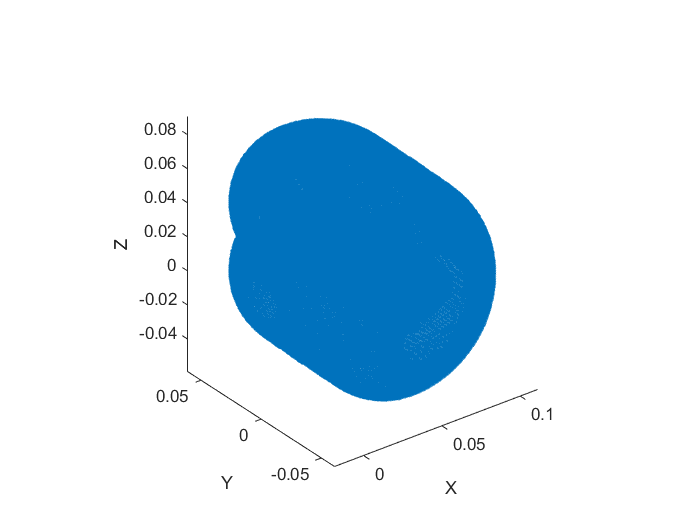

figure(1)
point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space_(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')

## plot solid

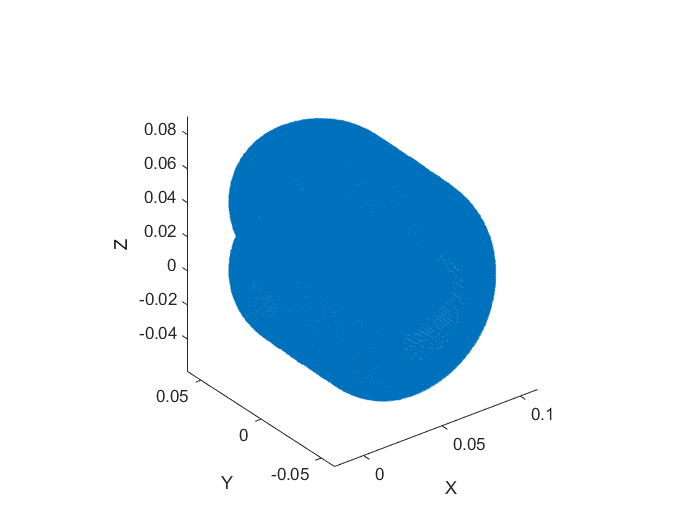

plot_squareXY([0.04 -5e-3 -0.05 1]',10e-3,5e-3,1,'r')

## choose point

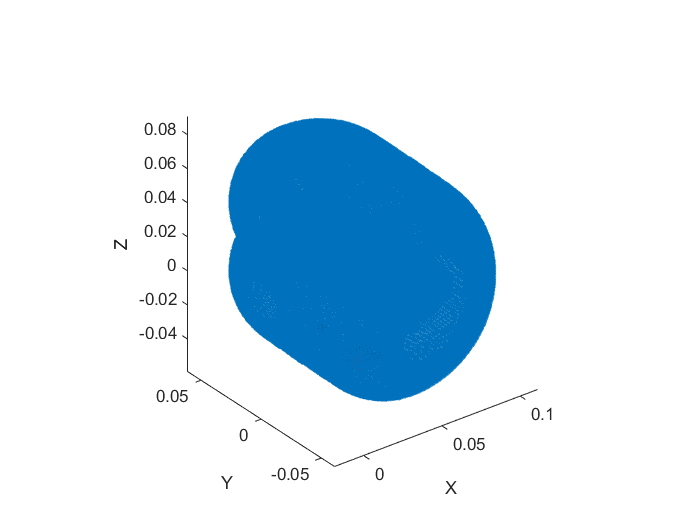

P1=[0.02 0 -0.02 1]';
P2=[0.041 6e-3 -0.045 1]';
P3=[0.049 6e-3 -0.045 1]';
P34=[0.052 4.5e-3 -0.045 1]';
P4=[0.051 0 -0.045 1]';
P45=[0.053 -4.5e-3 -0.045 1]';
P5=[0.045 -6e-3 -0.045 1]';
points=[P1 P2 P3 P34 P4 P45 P5];
hold on
plot3(points(1,:),points(2,:),points(3,:),'*k',"LineWidth",3)

Q=TR4_invNumeric(points(1:3,:),link,1000,Con);

## compute trajectory

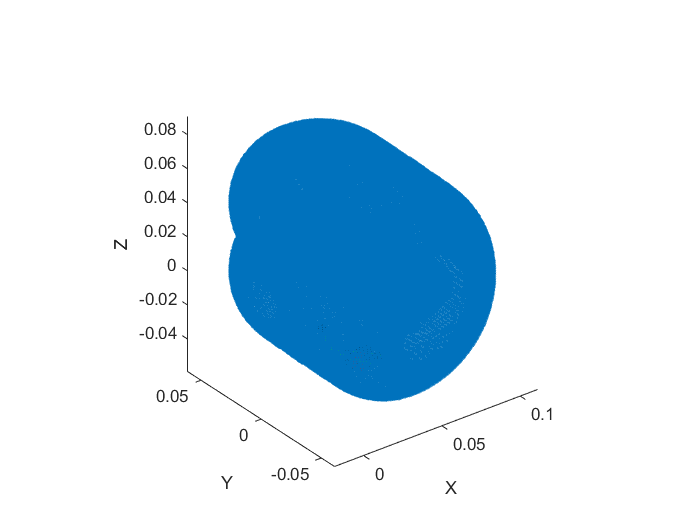

F=zeros(21,1);
[Q1,Qp1,Qpp1,Fq1,T1,X1,Xp1,Xpp1]=TR4_move([P1(1:3) P2(1:3)],1,@Cicloidale,link,M,F,'minimum_time_C',Con);
[Q2,Qp2,Qpp2,Fq2,T2,X2,Xp2,Xpp2]=TR4_move([P2(1:3) P3(1:3)],5,@Cicloidale,link,M,F,'linear',Con,Q1(end,:)');
[Q3,Qp3,Qpp3,Fq3,T3,X3,Xp3,Xpp3]=TR4_move([P3(1:3) P34(1:3) P4(1:3)],5,@Cicloidale,link,M,F,'circular',Con,Q2(end,:)');
[Q4,Qp4,Qpp4,Fq4,T4,X4,Xp4,Xpp4]=TR4_move([P4(1:3) P45(1:3) P5(1:3)],5,@Cicloidale,link,M,F,'circular',Con,Q3(end,:)');
[Q5,Qp5,Qpp5,Fq5,T5,X5,Xp5,Xpp5]=TR4_move([P5(1:3) P1(1:3)],1,@Cicloidale,link,M,F,'minimum_time_C',Con,Q4(end,:)');
plot3(X1(:,1),X1(:,2),X1(:,3),'g',"LineWidth",2)
plot3(X2(:,1),X2(:,2),X2(:,3),'g',"LineWidth",2)
plot3(X3(:,1),X3(:,2),X3(:,3),'g',"LineWidth",2)
plot3(X4(:,1),X4(:,2),X4(:,3),'g',"LineWidth",2)
plot3(X5(:,1),X5(:,2),X5(:,3),'g',"LineWidth",2)

## assemble trajectory with pauses

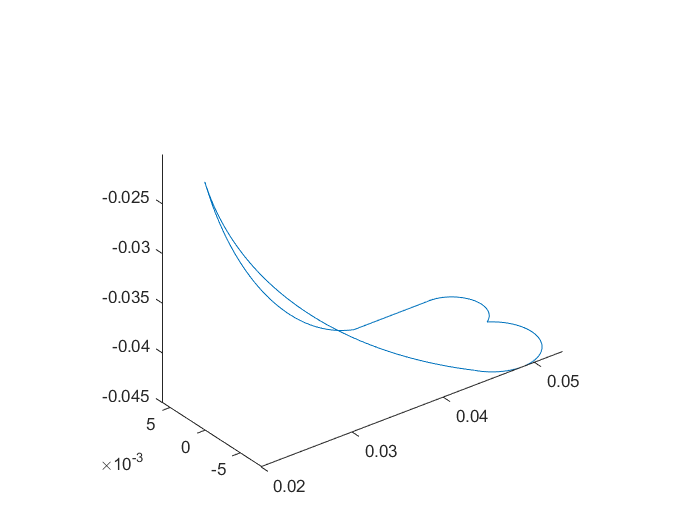

close all
Q_={Q1 Q2 Q3 Q4 Q5};
Qp_={Qp1 Qp2 Qp3 Qp4 Qp5};
Qpp_={Qpp1 Qpp2 Qpp3 Qpp4 Qpp5};
X_={X1 X2 X3 X4 X5};
Xp_={Xp1 Xp2 Xp3 Xp4 Xp5};
Xpp_={Xpp1 Xpp2 Xpp3 Xpp4 Xpp5};
T_={T1 T2 T3 T4 T5};
Fq_={Fq1 Fq2 Fq3 Fq4 Fq5};
[Q,Qp,Qpp,Fq,T,X,Xp,Xpp]=pauses(Q_,Qp_,Qpp_,Fq_,T_,X_,Xp_,Xpp_,1);
figure
plot3(X(:,1),X(:,2),X(:,3))
axis equal

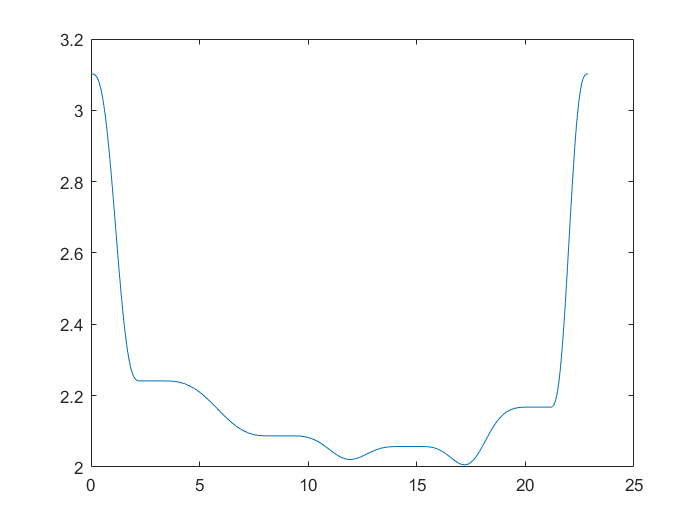

plot(T,Q(:,3))

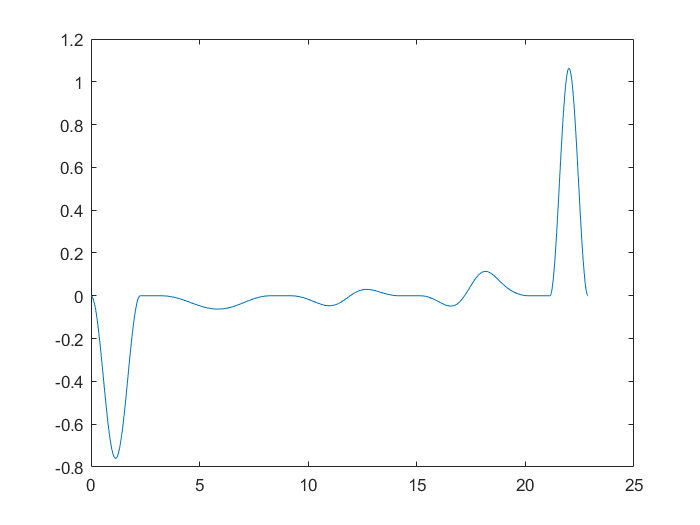

plot(T,Qp(:,3))

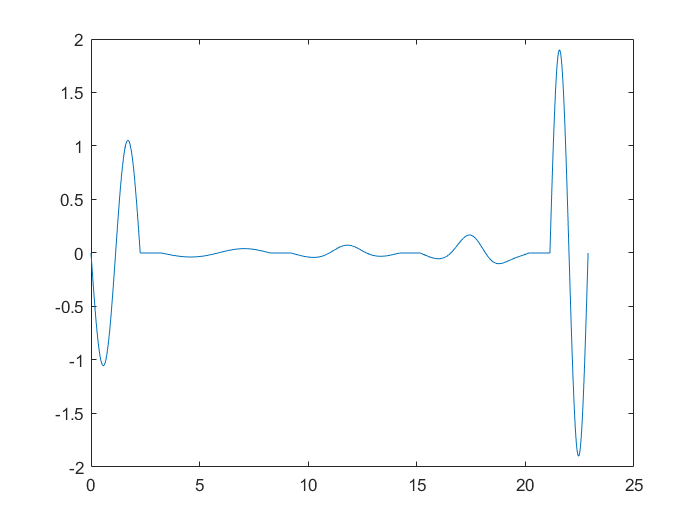

plot(T,Qpp(:,3))

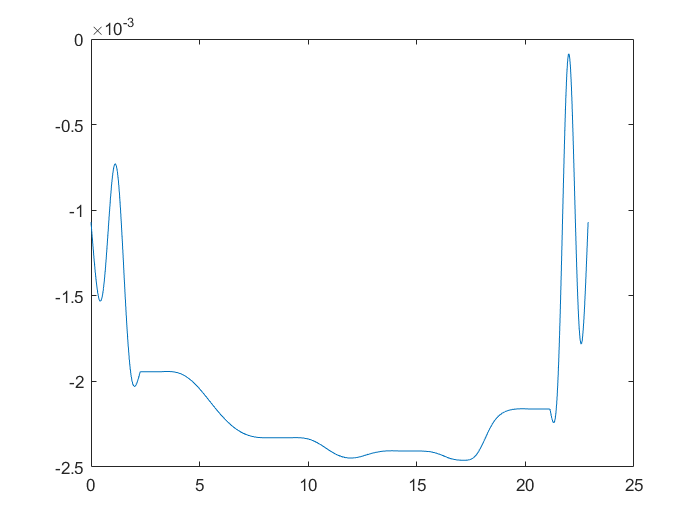

plot(T,Fq(:,1))

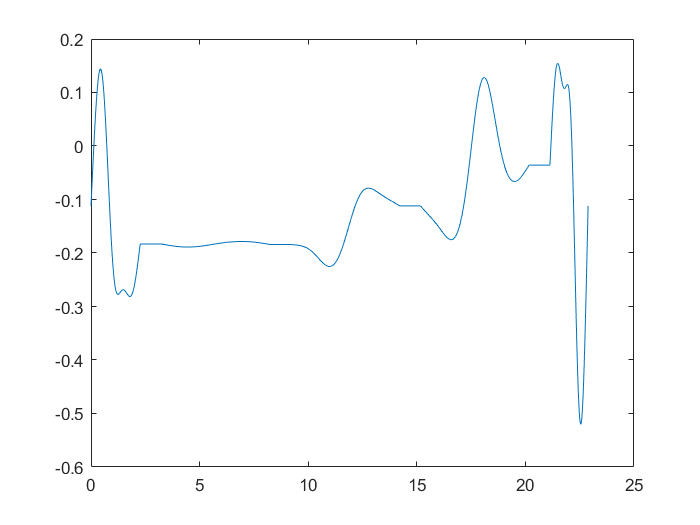

plot(T,Fq(:,2))

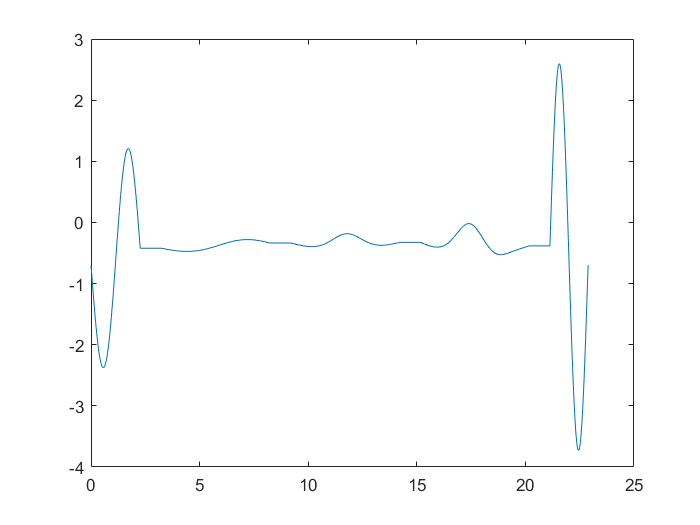

plot(T,Fq(:,3))

## plot trajectory

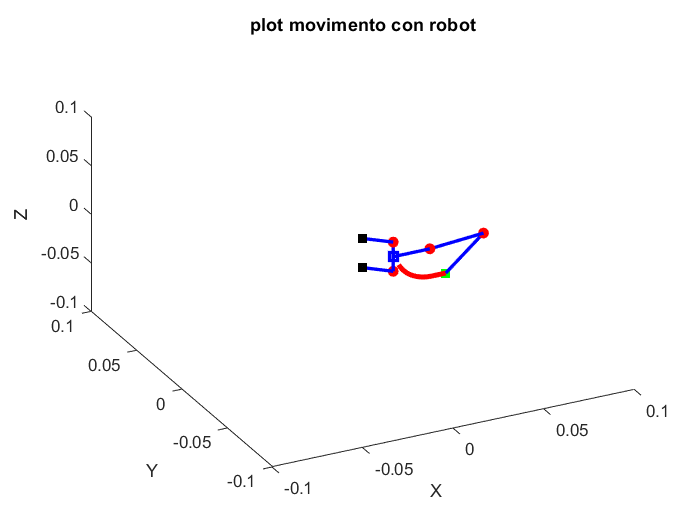

close all
TR4_plot_trajectory(link,Q,10,1)

axis equal

function [Q,Qp,Qpp,Fq,T,X,Xp,Xpp]=pauses(Q_,Qp_,Qpp_,Fq_,T_,X_,Xp_,Xpp_,TOP)
Q=cell2mat(Q_(1));
Qp=cell2mat(Qp_(1));
Qpp=cell2mat(Qpp_(1));
X=cell2mat(X_(1));
Xp=cell2mat(Xp_(1));
Xpp=cell2mat(Xpp_(1));
Fq=cell2mat(Fq_(1));
T=cell2mat(T_(1));

for i=2:length(Q_)
    dt=T(end)-T(end-1);
    division=floor(TOP/dt);
    pause_=(0:dt:division*dt)+T(end);
    T=[T pause_];
    for j=1:division+1
        Q=[Q ;Q(end,:)];
        Qp=[Qp ;Qp(end,:)];
        Qpp=[Qpp ;Qpp(end,:)];
        X=[X;X(end,:)];
        Xp=[Xp;Xp(end,:)];
        Xpp=[Xpp;Xpp(end,:)];
        Fq=[Fq;Fq(end,:)];
    end
    Q=[Q; cell2mat(Q_(i))];
    Qp=[Qp ;cell2mat(Qp_(i))];
    Qpp=[Qpp ;cell2mat(Qpp_(i))];
    X=[X;cell2mat(X_(i))];
    Xp=[Xp;cell2mat(Xp_(i))];
    Xpp=[Xpp;cell2mat(Xpp_(i))];
    Fq=[Fq;cell2mat(Fq_(i))];
    T=[T cell2mat(T_(i))+T(end)];
end
end